# Dimensionality Reduction: Ship Loader Data from many files

Data Science for Engineers II WS2024/25

Author: Dimitar Ninevski

## Prepare workspace

close all;
clear;

## Select directory with files

path = uigetdir;
files = dir(path);
nrFiles = length(files);

## Go through each file and analyse the data

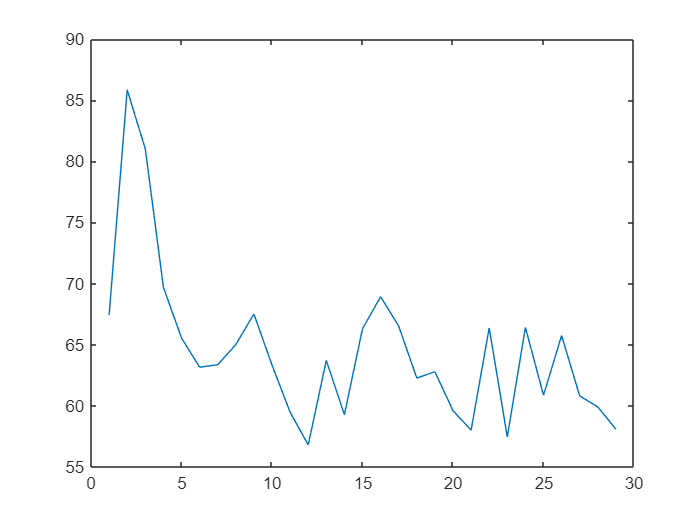

for i = 3:nrFiles
    fileName = files(i).name;
    load(fileName);
    % Convert to matrix
    dataMat = dataTT{:,:};
    % Extract time and channel names
    timeVec = dataTT.Properties.RowTimes;
    channelNames = dataTT.Properties.VariableNames;
    % Remove NaNs from data
    rowsWithNans = sum(isnan(dataMat),2);
    dataMat(rowsWithNans>0, :) = [];
    % Normalize data
    stdData = std(dataMat);
    stdData(stdData==0) = 1;
    dataMat = (dataMat - mean(dataMat))./stdData;
    % Perform PCA
    [U,S,V] = svd(dataMat, 0);
    nrVarSaved = 3;
    % Compute the variance saved
    sumOfDiag = sum(sum(S.^2));
    matVar = 100*S.^2./sumOfDiag;
    varKept(i-2) = sum(sum(matVar(1:nrVarSaved, 1:nrVarSaved)));
end
figure
plot(varKept);


return

## Load data

load('LoaderA14-03-12');

Convert data to matrix

dataMat = dataTT{:,:};

Extract channel names and time vector

timeVec = dataTT.Properties.RowTimes;
channelNames = dataTT.Properties.VariableNames;

## Visualize data

nrChannels = size(dataMat, 2);
figure
for i = 1:nrChannels
    subplot(11,1,i)
    plot(timeVec, dataMat(:,i));
    ylabel(channelNames{i});
end

## Remove NaNs from data

rowsWithNans = sum(isnan(dataMat),2);
dataMat(rowsWithNans>0, :) = [];

## Perform PCA

First step: normalize data

stdData = std(dataMat);

Replace all zero standard deviations with a 1, so that we can avoid problems with division by 0.

stdData(stdData==0) = 1;
dataMat = (dataMat - mean(dataMat))./stdData;

Now perform SVD

[U,S,V] = svd(dataMat, 0);
nrVarSaved = 3;
%dimRedData = dataMat*V(1:nrVarSaved,:);
dimRedData = U(:,1:nrVarSaved)*S(1:nrVarSaved,1:nrVarSaved);

## Plot results

xSc = dimRedData(:,1);
ySc = dimRedData(:,2);
zSc = dimRedData(:,3);
size = 3*ones(size(xSc));
colors = 1:length(xSc);
figure
scatter3(xSc, ySc, zSc,size,colors);
colorbar;

## Compute amount of variance kept

sumOfDiag = sum(sum(S.^2));
matVar = 100*S.^2./sumOfDiag;
varKept = sum(sum(matVar(1:nrVarSaved, 1:nrVarSaved)))
